clc
clear all
close all 

% System definition

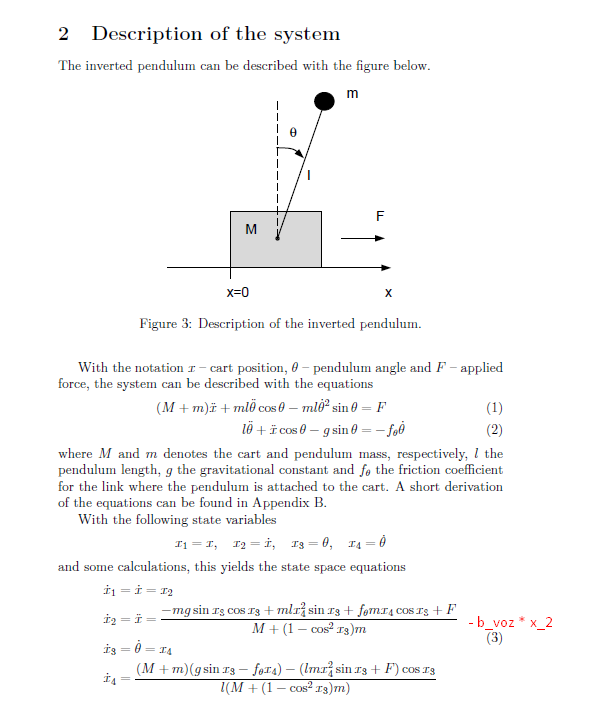

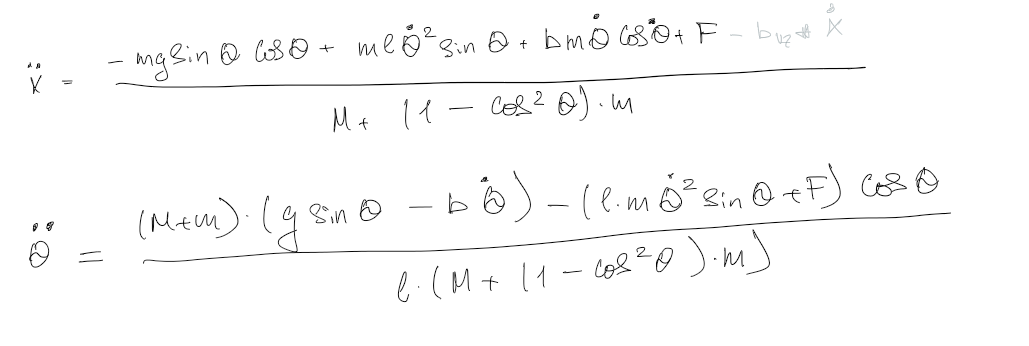

    M = 0.5     % mass of the cart

M = 0.5000

    m = 0.2     % mass of the pendulum

m = 0.2000

    b = 0.1     % coefficient of the friction rotation

b = 0.1000

    b_c = 0.5   % coefficient of the friction translation

b_c = 0.5000

    I = 0.006   % mass moment of inertia of the pendulum

I = 0.0060

    g = 9.81    % acceleration of gravity

g = 9.8100

    l = 0.3     % length to pendulum center of mass    

l = 0.3000

#### Rovnice a linearizace:


$$$
\ddot{x} = \frac{-m.g.sin(\theta).cos(\theta) + m.l.\dot{\theta}^2.sin(\theta) + b.m.\dot{\theta}.cos(\dot{\theta}) + F -b_{vz}.\dot{x}}{M+(1-cos^2(\theta)).m}\\
\ddot{\theta} = \frac{(M+m)(g.sin(\theta)-b.\dot{\theta})-(l.m.\dot{\theta}^2.sin(\theta)+F).cos(\theta)}{l.(M+(1-cos^2(\theta)).m)}
$$$



$$$
x = 
\pmatrix{
       x \cr
       \dot{x} \cr
       \theta \cr
       \dot{\theta}
} 
= 
\pmatrix{
       x_1 \cr
       x_2 \cr
       x_3 \cr
       x_4
} 
\\

\ddot{x} = \frac{-m.g.sin(\theta).cos(\theta) + m.l.\dot{\theta}^2.sin(\theta) + b.m.\dot{\theta}.cos(\dot{\theta}) + F -b_{vz}.\dot{x}}{M+(1-cos^2(\theta)).m}\\
\ddot{\theta} = \frac{(M+m)(g.sin(\theta)-b.\dot{\theta})-(l.m.\dot{\theta}^2.sin(\theta)+F).cos(\theta)}{l.(M+(1-cos^2(\theta)).m)}\\

\dot{x}_1 = x_2\\
\dot{x}_2 = \frac{-m.g.sin(x_3).cos(x_3) + m.l.x_{4}^2.sin(x_3) + b.m.x_{4}.cos(x_4) + F -b_{vz}.x_2}{M+(1-cos^2(x_3)).m}\\
\dot{x}_3 = x_4\\
\dot{x}_4 = \frac{(M+m)(g.sin(x_3)-b.x_4)-(l.m.x_{4}^2.sin(x_3)+F).cos(x_3)}{l.(M+(1-cos^2(x_3)).m)}
$$$
